## **Questions 6-7 can be solved using the Left Heart Model.**

• The Full Heart Model does not have a specific question but must be completed regardless. 

• Remember to start each question off from “baseline” healthy values for each model. Refer to the Parameters & Sources section of the “Cardiovascular Project Instructions Fall 2025” document for some details on how you can do this.

### Left Heart Model (NEW)

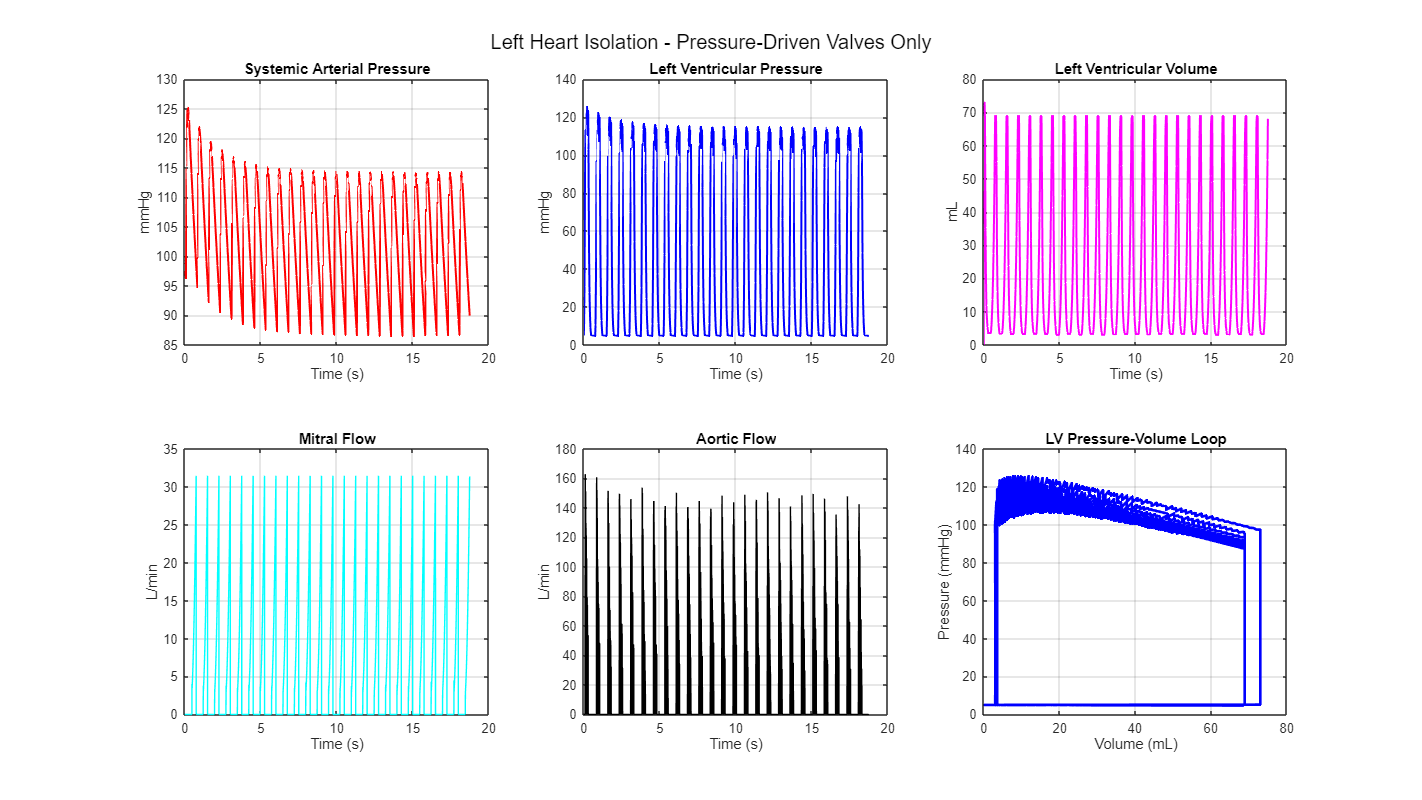

clear; clc; close all;

% PARAMETERS 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-5; % Time step 
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

Rmi = 0.01; % Mitral resistance
Rao = 0.01; % Aortic resistance
Rs  = 17.5*1.107; % Systemic resistance
Csa = 0.0015*1.2; % Systemic arterial compliance
Ppv = 5; % Constant pulmonary venous pressure (left atrial proxy)

% INITIAL CONDITIONS

% PREALLOCATE
Psa = zeros(size(t)); Psa(1) = 100;
Plv = zeros(size(t)); Plv(1) = 5;
Vlv = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 

CLV = @(t) compute_dynamic_compliance(t, T, ts, tauS, tauD, CLVS, CLVD);

function CV=CV_now(t,T,ts,tauS,tauD,CVS,CVD)
% Compliance of the Ventricle Testing
% CVS and CVD refer to the compliance of either the right or left
% ventricle during systole and diastole, respectively. CLVS, CRVS,
% CLVD, and CRVD.
% Remainder of cardiac cycle
tc=rem(t,T);
    for ii=1:length(tc) % For every time point that’s in tc
        if tc(ii)<ts % If tc is less than ts, systole
             e=(1-exp(-tc(ii)/tauS))/(1-exp(-ts/tauS));
             CV(ii)=CVD*(CVS/CVD)^e;
        else % If tc is greater than ts, diastole
             e=(1-exp(-(tc(ii)-ts)/tauD))/(1-exp(-(T-ts)/tauD));
             CV(ii)=CVS*(CVD/CVS)^e;
        end
    end
end

% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD);
    Clv_next = CV_now(t(k)+dt,T,ts,tauS,tauD,CLVS,CLVD);
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv, Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows
    Qmi = S_mi * (Ppv - Plv(k)) / Rmi;
    Qao = S_ao * (Plv(k) - Psa(k)) / Rao;
    Qs  = Psa(k) / Rs; % Assuming Psv << Psa
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao - Qs) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi - Qao)) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1600 900]);
sgtitle('Left Heart Isolation - Pressure-Driven Valves Only');

subplot(2,3,1); 
plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); 
grid on;
title('Systemic Arterial Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,2); 
plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,3); 
plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Volume'); 
ylabel('mL'); 
xlabel('Time (s)');

subplot(2,3,4); 
plot(t_sec(idx), valve_open(Ppv, Plv(idx)).* (Ppv - Plv(idx))/Rmi, 'c'); 
grid on;
title('Mitral Flow');
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,5); 
plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); 
grid on;
title('Aortic Flow'); 
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,6); 
plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); 
grid on;
title('LV Pressure-Volume Loop');
xlabel('Volume (mL)'); 
ylabel('Pressure (mmHg)');

## **Question 6: Valvular Heart Disease (Stenosis)**

**• Background:** Stenosis is a type of heart valve disease in which the valve opening becomes narrowed or stiffened, restricting the normal forward flow of blood. Instead of opening fully and allowing smooth passage, the thickened or calcified valve creates increased resistance that the heart must overcome to push blood through. This elevated workload can lead to pressure buildup, chamber hypertrophy, and eventually heart failure if untreated. Stenosis most commonly affects the elderly due to age-related calcific degeneration, though it can also result from rheumatic fever or congenital malformations. Because the valve tissue cannot be restored once significantly calcified or fibrotic, valve replacement surgery remains the primary and often only effective treatment for severe cases.

**• Task:** Using the Left Heart Model, simulate mitral and aortic stenosis by increasing the resistances `RMi` and `RAo`, respectively, enough to see a measurable change in the output graphs. Document the uncompensated effects on at least the left ventricular pressure (`PLV`), systemic arterial pressure (`Psa`), and stroke volume.

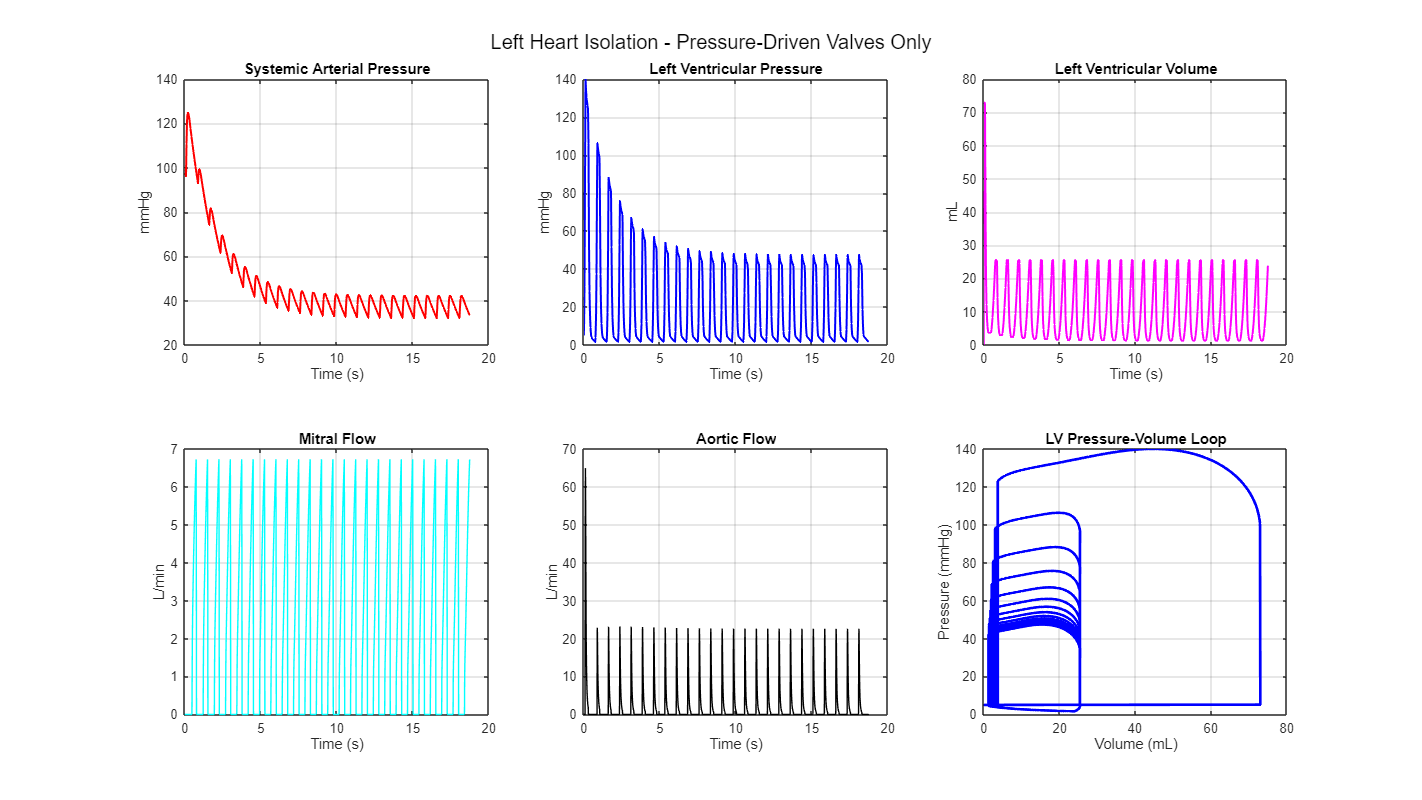

clear; clc; close all;

% PARAMETERS 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-5; % Time step 
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

Rmi = 0.5; % Mitral resistance
Rao = 0.5; % Aortic resistance
Rs  = 17.5*1.107; % Systemic resistance
Csa = 0.0015*1.2; % Systemic arterial compliance
Ppv = 5; % Constant pulmonary venous pressure (left atrial proxy)

% INITIAL CONDITIONS
Psa(1) = 1000;
Plv(1) = 50;

% PREALLOCATE
Psa = zeros(size(t)); Psa(1) = 100;
Plv = zeros(size(t)); Plv(1) = 5;
Vlv = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 

CLV = @(t) compute_dynamic_compliance(t, T, ts, tauS, tauD, CLVS, CLVD);


% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD);
    Clv_next = CV_now(t(k)+dt,T,ts,tauS,tauD,CLVS,CLVD);
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv, Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows
    Qmi = S_mi * (Ppv - Plv(k)) / Rmi;
    Qao = S_ao * (Plv(k) - Psa(k)) / Rao;
    Qs  = Psa(k) / Rs; % Assuming Psv << Psa
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao - Qs) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi - Qao)) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1600 900]);
sgtitle('Left Heart Isolation - Pressure-Driven Valves Only');

subplot(2,3,1); 
plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); 
grid on;
title('Systemic Arterial Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,2); 
plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,3); 
plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Volume'); 
ylabel('mL'); 
xlabel('Time (s)');

subplot(2,3,4); 
plot(t_sec(idx), valve_open(Ppv, Plv(idx)).* (Ppv - Plv(idx))/Rmi, 'c'); 
grid on;
title('Mitral Flow');
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,5); 
plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); 
grid on;
title('Aortic Flow'); 
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,6); 
plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); 
grid on;
title('LV Pressure-Volume Loop');
xlabel('Volume (mL)'); 
ylabel('Pressure (mmHg)');

% entradndo y salinedo meonos sangre x calcuficacion, baj avolumen y sangre

**Question 7: Valvular Heart Disease (Insufficiency)**

• Background: Insufficiency (regurgitation) occurs when a heart valve fails to close completely, allowing blood to leak backward through it when it should be sealed. Under normal conditions, heart valves act as one-way gates that maintain forward blood flow, but when their leaflets are damaged, deformed, or weakened due to causes such as rheumatic disease, infection, congenital malformation, or tissue degeneration, the valve cannot form a tight seal. This results in pathological backflow, forcing the heart to pump extra volume to maintain circulation, which can eventually cause chamber dilation, increased workload, and heart failure if left untreated.

• Task: Using the Left Heart Model, model valve leakage (insufficiency/regurgitation). For the mitral valve, modify its flow equation from `QMi` `=` `SMi` `*` `(Ppv` `-` `PLV)` `/` `RMi` to: `QMi` `=` `[SMi` `/` `RMiF` `+` `(1` `-` `SMi)` `/` `RMiB]` `*` `(Ppv` `-` `PLV) `where `RMiF` is the forward resistance (ideally 0 but usually small, i.e 0.01) and `RMiB` is the new, finite backflow resistance (ideally infinity but usually just very large, i.e 10000)). Apply a similar modification to the aortic valve (`RAoF` `and` `RAoB`). Investigate the hemodynamic consequences of reducing `RMiB` without altering `RAoB` and then vice versa. For a healthy mitral valve `RMiF` is very small and `RMiB` is very large, similar for the aortic valve.

clear; clc; close all;

% PARAMETERS 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-5; % Time step 
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

Rmi = 0.5; % Mitral resistance
Rao = 0.5; % Aortic resistance
Rs  = 17.5*1.107; % Systemic resistance
Csa = 0.0015*1.2; % Systemic arterial compliance
Ppv = 5; % Constant pulmonary venous pressure (left atrial proxy)

% INITIAL CONDITIONS
Psa(1) = 1000;
Plv(1) = 50;

% PREALLOCATE
Psa = zeros(size(t)); Psa(1) = 100;
Plv = zeros(size(t)); Plv(1) = 5;
Vlv = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 

CLV = @(t) compute_dynamic_compliance(t, T, ts, tauS, tauD, CLVS, CLVD);


% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now = CV_now(t(k),T,ts,tauS,tauD,CLVS,CLVD);
    Clv_next = CV_now(t(k)+dt,T,ts,tauS,tauD,CLVS,CLVD);
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv, Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows
    Qmi = [S_mi / Rmi + (1 - S_mi) / Rmi] *(Ppv - Plv);
    Qao = S_ao * (Plv(k) - Psa(k)) / Rao;
    Qs  = Psa(k) / Rs; % Assuming Psv << Psa
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao - Qs) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi - Qao)) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

Unable to perform assignment because the left and right sides have a different number of elements.


% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1600 900]);
sgtitle('Left Heart Isolation - Pressure-Driven Valves Only');

subplot(2,3,1); 
plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); 
grid on;
title('Systemic Arterial Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,2); 
plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Pressure'); 
ylabel('mmHg'); 
xlabel('Time (s)');

subplot(2,3,3); 
plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); 
grid on;
title('Left Ventricular Volume'); 
ylabel('mL'); 
xlabel('Time (s)');

subplot(2,3,4); 
plot(t_sec(idx), valve_open(Ppv, Plv(idx)).* (Ppv - Plv(idx))/Rmi, 'c'); 
grid on;
title('Mitral Flow');
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,5); 
plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); 
grid on;
title('Aortic Flow'); 
ylabel('L/min'); 
xlabel('Time (s)');

subplot(2,3,6); 
plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); 
grid on;
title('LV Pressure-Volume Loop');
xlabel('Volume (mL)'); 
ylabel('Pressure (mmHg)');